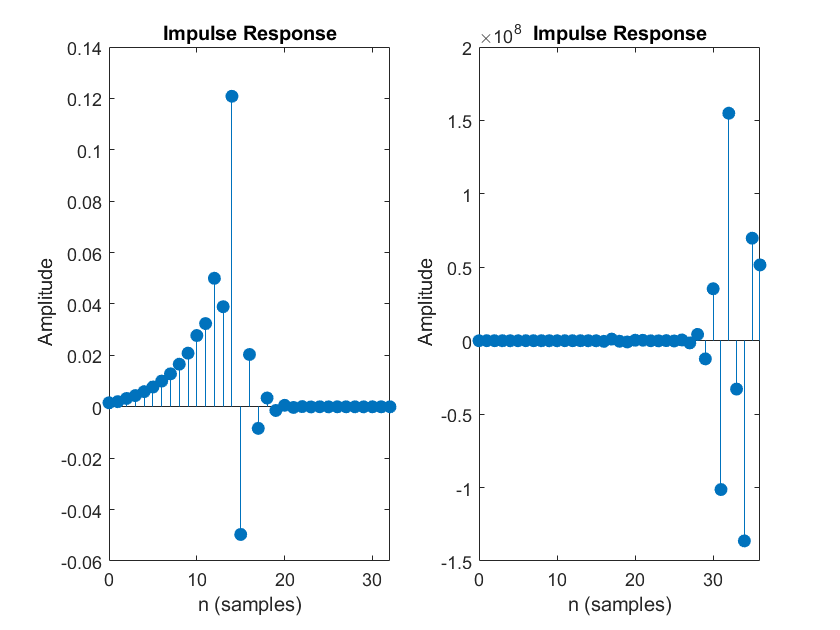

clc;
close all;
clear all;

h = [-2 -4 6 3];
N = 32;
CoefPhilter = xcorr(h,N);
CoefPhilter = CoefPhilter(N+1:end); % одностороння КФ ИХ канала
MatrixCor = toeplitz(CoefPhilter);
p = zeros(N+1, 1);
k0 = round((N-length(h))/2);
p(k0:k0+length(h)-1) = fliplr(h);
w = MatrixCor\p;
subplot(1,2,1) 
impz(w);
subplot(1,2,2) 
impz(h,w);